clear all

% 480P videos / behavior file / DLC labels
% video_to_load = './behaviorVids/Do20220225.mp4';
% video_to_load = './behaviorVids/Do20220302.mp4';
video_to_load = 'Se20220314.mp4';
vidPath = ['/mnt/DataDrive2/treeshrew/data_preproc/treeshrew_videos/ObjectRecognition/',video_to_load];

datfile = './shrewData.mat';

dlcvideo_meta = VideoReader(vidPath);
max_frame = dlcvideo_meta.NumFrames;

RGB = uint8(readFrame(dlcvideo_meta));
clear dlcvideo_meta

fig1 = figure();
imshow(RGB)
title('Draw a rectangle within the screen')
L = superpixels(RGB,500);
f1 = drawrectangle('Color','g');
foreground = createMask(f1,RGB);
fig2 = figure();
imshow(RGB)
title('Draw a rectangle indicating the background')
b1 = drawrectangle(gca,'Color','r');
background = createMask(b1,RGB);

% this shows what is identified as the screen - precision doesn't matter
% too much, change in intensity is what matters
BW = lazysnapping(RGB,L,foreground,background);
delete(fig1);
delete(fig2);


Redoing target definition 


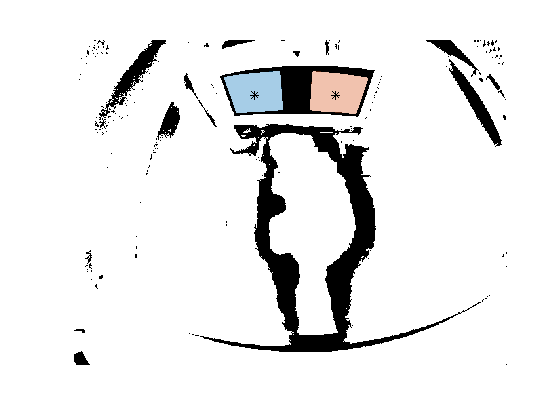

Targets are good. 


dlcvideo_meta = VideoReader(vidPath);

% now we look at changes in intensity over the first 1000 frames (could be
% even less) to pull out the first trial's start and end frames
frameRange = 100:200;
nframes = length(frameRange);
dlcvideo = nan(size(RGB,1),size(RGB,2),size(RGB,3),nframes);
ii=1;
for curr_tr=1:max(frameRange)
    fr = readFrame(dlcvideo_meta);
    if ismember(curr_tr,frameRange)
        dlcvideo(:,:,:,ii) = fr;
        ii=ii+1;
    end
end
clear dlcvideo_meta

mint = zeros(nframes,1);
for curr_tr=1:nframes
    maskedRgbImage = bsxfun(@times, dlcvideo(:,:,:,curr_tr), cast(BW, 'like', dlcvideo(:,:,:,curr_tr)));
    mint(curr_tr)=mean(maskedRgbImage(:));
end

mintensity = mint - mean(mint);
int_th = -(max(abs(mintensity))-0.5);
% int_th = -0.6;

% make cells with the frames for each trial in im_on
side_on = find(mintensity<int_th);
if length(side_on)==length(mintensity)
    side_on = [];
end

% this is the real image we will work with now that we are using frames
% with clearly defined images on the screen
ex_tr = 1;
I = uint8(mean(dlcvideo(:,:,:,side_on(ex_tr)),4));

% binarize the image with imflatfield and imadjust
sigma = 30;
filtthresh = 140;

% now the user can click the middle of the two stimuli so I can extract the
% objects with centroids closest to where we click
targets_good='N';
num_targetpoints_to_define = 2;

% now the user can click the middle of the two stimuli so I can extract the
% objects with centroids closest to where we click
clf('reset')
fig3 = figure();
imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
title('Click on image to identify left then right stimulus.')
[target_x,target_y]=ginput(num_targetpoints_to_define);
target_colors=jet(length(target_x));
hold on
% some of the earlier videos were flipped horizontally when uploaded,
% but all recent videos should be fine, i.e. input 'Y'
yn_flip = input('Is the video flipped correctly? Y/N: ','s');
if strcmp(yn_flip,'N')
    target_xlist = target_x([2 1],:);
    target_ylist = target_y([2 1],:);
else
    target_xlist = target_x;
    target_ylist = target_y;
end
close(fig3);

while ~strcmp(targets_good,'Y')
    clf('reset')
    fig3 = figure();
    imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
    hold on;

    grayI = rgb2gray(I);
    J = imadjust(imflatfield(grayI,sigma,'FilterSize',115))<filtthresh;
    
    % now use this function regionprops which extracts statistics for "objects"
    % in the image - I extracted the area of the object, the centroid, and
    % extrema
    stats = regionprops('table',J,'Area','Centroid','Extrema','ConvexHull');
    
    % only look at objects with an area > 2 (it will extract single pixels so
    % want to make sure noise isn't confusing it
    stats_side = stats(stats.Area>2,:);
    centroids = cat(1,stats.Centroid);
    
    % identify which objects to extract based on centroid/click location
    cent = zeros(1,num_targetpoints_to_define);
    pgon = {};
    for i = 1:num_targetpoints_to_define
        dist = sqrt((stats_side.Centroid(:,1) - target_xlist(i)).^2 + (stats_side.Centroid(:,2) - target_ylist(i)).^2);
        cent(i) = find(dist == min(dist));
        % convert extrema to polygons to plot
        pgon{i} = polyshape(stats_side.ConvexHull{cent(i)}(:,1),stats_side.ConvexHull{cent(i)}(:,2));
    end
    % will plot masks on top of video frame - make sure they cover the full
    % stimulus area, if not, input 'N' and try a new threshold
    imshow(J)
    hold on;
    plot(pgon{1})
    plot(pgon{2})
    plot(target_xlist(1),target_ylist(1),'k*')
    plot(target_xlist(2),target_ylist(2),'k*')
    hold on
    targets_good=input('Do the targets look good? Y/N: ','s');
    if ~strcmp(targets_good,'Y')
        fprintf('Redoing target definition \n')
        filtthresh = input(['New filter threshold (previously ',num2str(filtthresh),'): ']);
        close(fig3);
    else
        fprintf('Targets are good. \n')
    end
end

LeftMask = poly2mask(stats_side.ConvexHull{cent(1)}(:,1),stats_side.ConvexHull{cent(1)}(:,2),size(J,1),size(J,2));
corners = detectHarrisFeatures(LeftMask,'MinQuality',0.05);
target_list_left = corners.selectStrongest(4).Location;

RightMask = poly2mask(stats_side.ConvexHull{cent(2)}(:,1),stats_side.ConvexHull{cent(2)}(:,2),size(J,1),size(J,2));
corners = detectHarrisFeatures(RightMask);
target_list_right = corners.selectStrongest(4).Location;

clf('reset')
fig3 = figure();
imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
hold on
scatter(target_list_left(:,1),target_list_left(:,2))
scatter(target_list_right(:,1),target_list_right(:,2))
% some of the earlier videos were flipped horizontally when uploaded,
% but all recent videos should be fine, i.e. input 'Y'
yn_corners = input('Do the corners look right? Y/N: ','s');
close(fig3);

if strcmp(yn_corners,'N')
    clf('reset')
    fig3 = figure();
    imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
    title('Click on image to identify corners of the left image.')
    [target_x,target_y]=ginput(4);
    target_list_left = [target_x,target_y];
    close(fig3);
    clf('reset')
    fig3 = figure();
    imagesc(uint8(dlcvideo(:,:,:,side_on(ex_tr)))); %display mean image across entire movie
    title('Click on image to identify corners of the right image.')
    [target_x,target_y]=ginput(4);
    target_list_right = [target_x,target_y];
    close(fig3);
end

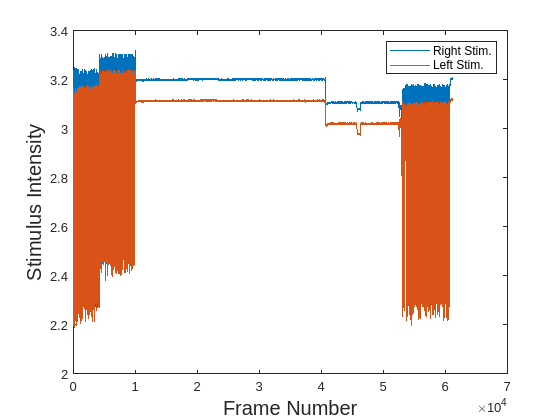

dlcvideo_meta = VideoReader(vidPath);
for curr_tr=1:max_frame
    dlcFrame = readFrame(dlcvideo_meta);
    maskedRgbImage = bsxfun(@times, dlcFrame, cast(RightMask, 'like', dlcFrame));
    rightside_intensity(curr_tr)=mean(maskedRgbImage(:));
    maskedRgbImage = bsxfun(@times, dlcFrame, cast(LeftMask, 'like', dlcFrame));
    leftside_intensity(curr_tr)=mean(maskedRgbImage(:));
end
clear dlcvideo_meta

% want to find periods of time where there are no trials within 100 frames
% so we can normalize each chunk of trials separately
thresh = find(abs(diff(rightside_intensity))>0.1);
findgaps = [0 thresh(diff(thresh)>100)];
len = length(rightside_intensity);

% for each chunk of trials we subtract the mean intensity during that
% period
for i = 1:length(findgaps)
    if i==length(findgaps)
        inter = findgaps(i)+1:len;
    else
        inter = findgaps(i)+1:findgaps(i+1);
    end
    rightside_inten_norm(inter) = rightside_intensity(inter) - min(rightside_intensity(inter));
    leftside_inten_norm(inter) = leftside_intensity(inter) - min(leftside_intensity(inter));
end

stim_thresh = 0.4;

figure();
plot(rightside_intensity)
hold on;
plot(leftside_intensity)
xlabel('Frame Number','FontSize',15)
ylabel('Stimulus Intensity','FontSize',15)
legend('Right Stim.','Left Stim.')

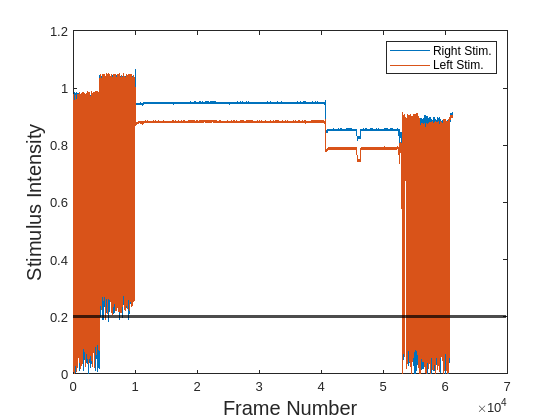


% plot the intensities post-normalization
figure();
plot(rightside_inten_norm)
hold on;
plot(leftside_inten_norm)
yline(stim_thresh,'k','linewidth',2)
xlabel('Frame Number','FontSize',15)
ylabel('Stimulus Intensity','FontSize',15)
legend('Right Stim.','Left Stim.')

% find frames for each image where the intensity < int_th (defined in main
% script) and save in new cell for right/left stims
rightside_on = find(rightside_inten_norm<stim_thresh);
right_diff = sum(diff(rightside_on)>1)+1;
right_on = cell(1,right_diff); k = 1;
for i = 1:length(rightside_on)-1
    right_on{k} = [right_on{k} rightside_on(i)];
    if rightside_on(i+1)-rightside_on(i)>1
        k = k+1;
    end
end
leftside_on = find(leftside_inten_norm<stim_thresh);
left_diff = sum(diff(leftside_on)>1)+1;
left_on = cell(1,left_diff); k = 1;
for i = 1:length(leftside_on)-1
    left_on{k} = [left_on{k} leftside_on(i)];
    if leftside_on(i+1)-leftside_on(i)>1
        k = k+1;
    end
end

% don't really need both right_on and left_on because if they are different
% lengths I set them equal to each other, but helps to keep track of the side
if length(left_on)~=length(right_on)
    y = find(min([length(left_on) length(right_on)]));
    if y==1
        right_on = left_on;
    else
        left_on = right_on;
    end
end

% if any trial lengths last 1 frame or have empty cells, I remove them -
% not sure if this actually happens, but it's a precaution
trlen = find(cellfun(@(x) length(x),right_on)>100 | cellfun(@(x) length(x),right_on)<2);
right_on(trlen) = [];
left_on(trlen) = [];

ii = 1;
num = 1;
dlcvideo_meta = VideoReader(vidPath);
dlcFrame = cell(1,length(right_on));
for curr_tr=1:max_frame
    if ismember(curr_tr, right_on{ii})
        dlcFrame{ii}(:,:,:,num) = readFrame(dlcvideo_meta);
        num = num+1;
    elseif curr_tr > max(right_on{ii})
        ii = ii+1;
        num = 1;
        if curr_tr >= max(right_on{end})
            break
        end
        readFrame(dlcvideo_meta);
    else
        readFrame(dlcvideo_meta);
    end
end
clear dlcvideo_meta


refimage = imread('target_0.png');
ref_h = size(refimage,1);
ref_w = size(refimage,2);

% precompute left corner ordering - unchanged across trials
target_left = nan(size(target_list_left));
xcenter = mean(target_list_left(:,1));
ycenter = mean(target_list_right(:,2));
for i = 1:size(target_list_left,1)
    xdist = target_list_left(i,1) - xcenter;
    ydist = target_list_left(i,2) - ycenter;
    if xdist>0 && ydist>0
        target_left(3,:) = target_list_left(i,:);
    elseif xdist<0 && ydist>0
        target_left(4,:) = target_list_left(i,:);
    elseif xdist>0 && ydist<0
        target_left(2,:) = target_list_left(i,:);
    elseif xdist<0 && ydist<0
        target_left(1,:) = target_list_left(i,:);
    end
end

% precompute right corner ordering - unchanged across trials
target_right = nan(size(target_list_right));
xcenter = mean(target_list_right(:,1));
ycenter = mean(target_list_right(:,2));
for i = 1:length(target_list_right)
    xdist = target_list_right(i,1) - xcenter;
    ydist = target_list_right(i,2) - ycenter;
    if xdist>0 && ydist>0
        target_right(3,:) = target_list_right(i,:);
    elseif xdist<0 && ydist>0
        target_right(4,:) = target_list_right(i,:);
    elseif xdist>0 && ydist<0
        target_right(2,:) = target_list_right(i,:);
    elseif xdist<0 && ydist<0
        target_right(1,:) = target_list_right(i,:);
    end
end

% precompute proj_location - depends only on yn_flip and refimage
if strcmp(yn_flip,'N')
    proj_location = [ref_w 0;0 0;0 ref_h;ref_w ref_h];
elseif strcmp(yn_flip,'Y')
    proj_location = [0 0;ref_w 0;ref_w ref_h;0 ref_h];
end

sigma = 30;

% load and preprocess all camel images once before the loop
camellist = imageDatastore('camels');
allcamels = zeros(ref_h, ref_w, length(camellist.Files), 'uint8');
for curr_image = 1:length(camellist.Files)
    temp = imread(camellist.Files{curr_image});
    if size(temp,3) > 1
        temp = rgb2gray(temp);
    end
    allcamels(:,:,curr_image) = imresize(temp, [ref_h ref_w]);
end

if strcmp(video_to_load(1:2),'Ry')
    % Do the same for rhinos (distractors)
    distlist=imageDatastore('rhinos');
    distractor='rhino';
else
    % load and preprocess all wrench images once before the loop
    distlist = imageDatastore('wrenches');
    distractor = 'wrench';
end

alldistractors = zeros(ref_h, ref_w, length(distlist.Files), 'uint8');
for curr_image = 1:length(distlist.Files)
    temp = imread(distlist.Files{curr_image});
    if size(temp,3) > 1
        temp = rgb2gray(temp);
    end
    alldistractors(:,:,curr_image) = imresize(temp, [ref_h ref_w]);
end

% flatten to 2D for batch corr: each column is one image
allcamels_flat  = reshape(single(allcamels),  [], size(allcamels,3));
alldistractors_flat = reshape(single(alldistractors), [], size(alldistractors,3));

% precompute category index vector and preallocate outputs
compImages_ind = [ones(size(allcamels,3),1); ones(size(alldistractors,3),1)*2];
imageTypes = {'camel',distractor};
camel_side = nan(1, length(right_on));
imageID    = nan(1, length(right_on));

for curr_tr = 1:length(right_on)

    % take average over all frames within a trial
    frames_avg = uint8(mean(dlcFrame{curr_tr},4));
    % extract the masked part of image & convert to grayscale
    maskedRgbImage = bsxfun(@times, frames_avg, cast(LeftMask, 'like', frames_avg));
    I = rgb2gray(maskedRgbImage);

    % calculate transformation and apply warp to image extracted from video
    transform = fitgeotrans(target_left, proj_location, 'projective');
    Jregistered = imwarp(I, transform, 'OutputView', imref2d(size(I)));
    Jregistered = Jregistered(1:ref_h, 1:ref_w, :);

    % code that removes average background gradient
    I = im2double(Jregistered);
    y = mean(I(:,1:100), 2);
    yb2 = imgaussfilt(y, sigma);
    Ic = bsxfun(@plus, I, yb2(1) - yb2);
    Jregistered = Ic;

    % now load all original camel images and compute pixelwise correlations with extracted frame
    compCImages = corr(single(Jregistered(:)), allcamels_flat);
    compWImages = corr(single(Jregistered(:)), alldistractors_flat);

    allComp = [compCImages compWImages];
    max_idx = find(allComp==max(allComp));
    left_image_type = compImages_ind(max_idx(1));
    left_image_corr = max(allComp);

    if compImages_ind(max_idx(1))==1
        im_idx = max_idx(1);
        filesplit = split(camellist.Files{im_idx},'_');
        left_imageID = str2num(filesplit{end}(1:end-4));
    elseif compImages_ind(max_idx(1))==2
        im_idx = max_idx(1) - size(allcamels,3);
        filesplit = split(distlist.Files{im_idx},'_');
        left_imageID = str2num(filesplit{end}(1:end-4));
    end

    % extract the masked part of image & convert to grayscale
    maskedRgbImage = bsxfun(@times, frames_avg, cast(RightMask, 'like', frames_avg));
    I = rgb2gray(maskedRgbImage);

    % calculate transformation and apply warp to image extracted from video
    transform = fitgeotrans(target_right, proj_location, 'projective');
    Jregistered = imwarp(I, transform, 'OutputView', imref2d(size(I)));
    Jregistered = Jregistered(1:ref_h, 1:ref_w, :);

    % code that removes average background gradient
    I = im2double(Jregistered);
    y = mean(I(:,1:100), 2);
    yb2 = imgaussfilt(y, sigma);
    Ic = bsxfun(@plus, I, yb2(1) - yb2);
    Jregistered = Ic;

    % now load all original camel images and compute pixelwise correlations with extracted frame
    compCImages = corr(single(Jregistered(:)), allcamels_flat);
    compWImages = corr(single(Jregistered(:)), alldistractors_flat);

    allComp = [compCImages compWImages];
    max_idx = find(allComp==max(allComp));
    right_image_type = compImages_ind(max_idx(1));
    right_image_corr = max(allComp);

    if compImages_ind(max_idx(1))==1
        filesplit = split(camellist.Files{max_idx(1)},'_');
        right_imageID = str2num(filesplit{end}(1:end-4));
    elseif compImages_ind(max_idx(1))==2
        im_idx = max_idx(1) - size(allcamels,3);
        filesplit = split(distlist.Files{im_idx},'_');
        right_imageID = str2num(filesplit{end}(1:end-4));
    end

    % if both images are identified as camels, choose the one with greater
    % correlation to be the camel
    if right_image_type==1 && left_image_type==1
        if right_image_corr > left_image_corr
            camel_side(curr_tr) = 2;
            imageID(curr_tr) = right_imageID;
        else
            camel_side(curr_tr) = 1;
            imageID(curr_tr) = left_imageID;
        end
    elseif right_image_type == 1
        camel_side(curr_tr) = 2;
        imageID(curr_tr) = right_imageID;
    elseif left_image_type == 1
        camel_side(curr_tr) = 1;
        imageID(curr_tr) = left_imageID;
    else
        camel_side(curr_tr) = NaN;
        imageID(curr_tr) = NaN;
    end

end

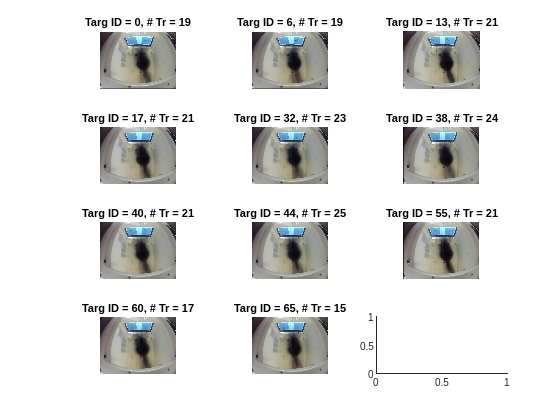

allImgs = unique(imageID);

figure();
tiledlayout('TileSpacing','compact');
nexttile;
for im = 1:length(allImgs)
imgID = allImgs(im);
trIdx = find(imageID==imgID);

avgFrame = nan(size(dlcFrame{1},1), size(dlcFrame{1},2), size(dlcFrame{1},3), length(trIdx));
for ii = 1:length(trIdx)
    trial = trIdx(ii);
    % imshow(dlcFrame{trial}(:,:,:,round(end/2)));
    avgFrame(:,:,:,ii) = dlcFrame{trial}(:,:,:,round(end/2));
end

posAvg = mean(avgFrame,4);
imshow(uint8(posAvg))
title(sprintf('Targ ID = %d, # Tr = %d', imgID, length(trIdx)))
nexttile;
end